# Correlate the base signal to the other signals and search for the peak

clc, clear, close all;

addpath OTHER
addpath DATASET

base_sample_rate = 1000;
display_points = 1000;

First load all the data

The base_wave file

filename_base = 'pianosync.wav';
[y,Fs] = audioread(filename_base); % 8kHz sample 
base_sync_1k = SigConToBin(y(:, 1)', Fs, base_sample_rate);
base_sync_1k = double(base_sync_1k)-0.5;

The EMG data

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
emg_sample_rate = 1000;
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sync = data(:, 3);
emg_sync_1k = SigConToBin(emg_sync, emg_sample_rate,base_sample_rate);
emg_sync_1k = double(emg_sync_1k)-0.5;

The blood data

raw_blood_data = load("perfusion_and_sync_19-Dec-2023-11_15_20.mat");
raw_blood_data_1k = raw_blood_data.fullDataSet(:, 1)';
blood_sample_rate = 1000;
raw_blood_data_1k = SigConToBin(raw_blood_data_1k, blood_sample_rate,base_sample_rate);
raw_blood_data_1k = double(raw_blood_data_1k)-0.5;

Video capture data

addpath OTHER
addpath DATASET
% Add path of 
% use this function example  
% 'data = BinToQTM(elina3.Trajectories.Unidentified.Data, [637.1 457.7 193.6], [10 10 10]);'

raw_video_data = load("elina3_nogapfilling.mat");
poi = [637.1 457.7 193.6];
tolerance_poi = [10 10 10];
video_sample_rate = 300;
video_capture_300 = double(QTMToBin(raw_video_data.elina3.Trajectories.Unidentified.Data, poi, tolerance_poi));

video_capture_1k = SigConToBin(video_capture_300, video_sample_rate, base_sample_rate);
video_capture_1k = double(video_capture_1k)-0.5;

Plot the data

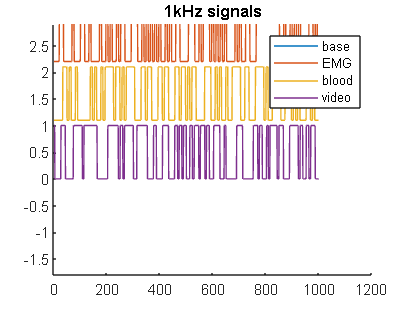

hold on
plot(base_sync_1k(1:display_points)+3.8);
plot(emg_sync_1k(1:display_points)+2.7);
plot(raw_blood_data_1k(1:display_points)+1.6);
plot(video_capture_1k(1000:1000+display_points)+0.5);

title("1kHz signals");
ylim([-1.8 2.9]);
legend("base", "EMG", "blood", "video");
hold off;

## Using xcorr

% Compute cross-correlation
[correlation_emg, lag_emg] = xcorr(base_sync_1k, emg_sync_1k);
correlation_emg = correlation_emg/max(correlation_emg); % normalize
correlation_emg = 20.*log10(correlation_emg); % to dB

[correlation_blood, lag_blood] = xcorr(base_sync_1k, raw_blood_data_1k);
correlation_blood = correlation_blood/max(correlation_blood); % normalize
correlation_blood = 20.*log10(correlation_blood); %to dB

[correlation_video, lag_video] = xcorr(base_sync_1k, video_capture_1k);
correlation_video = correlation_video/max(correlation_video); % normalize
correlation_video = 20.*log10(correlation_video); % to dB

% Plot cross-correlation
figure;

subplot(3,1,1);
plot(lag_emg, correlation_emg);

xlabel('Lag');
ylabel('Correlation in dB');
ylim([-40 1]);
xlim([2000 6000]);
title('Cross-correlation emg');

subplot(3,1,2);
plot(lag_blood, correlation_blood);

xlabel('Lag');
ylabel('Correlation in dB');
ylim([-40 1]);
xlim([-5000 5000]);
title('Cross-correlation blood');

subplot(3,1,3);
plot(lag_video, correlation_video);

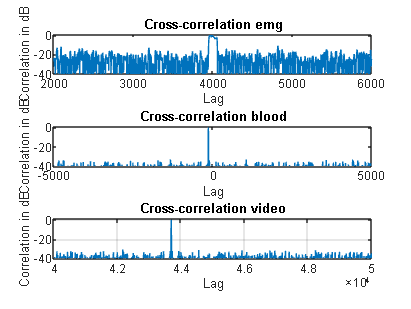

xlabel('Lag');
ylabel('Correlation in dB');
ylim([-40 1]);
xlim([40000 50000]);
title('Cross-correlation video');

grid on;

## Find EMG original sample freq

%TODO
% Het EMG signaal heeft altijd een verschuiving omdat het niet 100% 1kHz is
% maar iets er rond. Als we kijken naar de correlatie grafiek, dan is dit
% te zien aan de breede band waardat de hoogste correlatie voorkomt.
figure
subplot(1,2,1);

plot(lag_emg, correlation_emg);

title("EMG correlation")
xlim([3800, 4200]);
ylim([-20, 1]);

% We vergelijken het met blood die een veel scherpere correlatie band
% heeft.
subplot(1,2,2);
plot(lag_blood, correlation_blood);

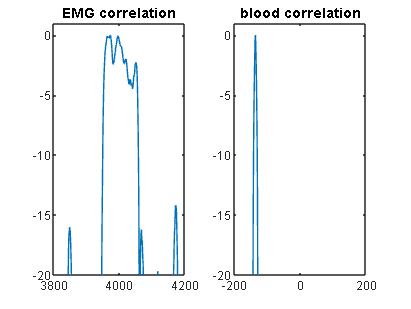

title("blood correlation")
xlim([-200, 200]);
ylim([-20, 1]);


% De EMG heeft dus een iets andere frequency, denk ik

# Align the signals with the base wave

[base_sync_1k, emg_sync_1k, lag_emg_1] = Align(base_sync_1k, emg_sync_1k);

Error using Align
Too many output arguments.

[base_sync_1k, raw_blood_data_1k, lag_blood_1] = Align(base_sync_1k, raw_blood_data_1k);
[base_sync_1k, video_capture_1k, lag_video_1] = Align(base_sync_1k, video_capture_1k);

full_lag =  min([lag_emg_1 lag_blood_1 lag_video_1]);
full_lag = 1*(full_lag == 0)+full_lag*(full_lag ~= 0);

figure
hold on
plot(base_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points) +2.2);
title("base sync bin 1kHz");

plot(emg_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points)+1.1);
title("EMC sync bin 1kHz");

plot(raw_blood_data_1k(abs(full_lag)-10:abs(full_lag)+display_points));
title("blood sync bin 1kHz");

plot(video_capture_1k(abs(full_lag)-10:abs(full_lag)+display_points)-1.1);
title("motion sync bin 1kHz");

ylim([-1.8 2.9]);
legend("base", "EMG", "blood", "video");
hold off;
% now cut off all the signals so we have a synced signal.
% find the lowest range
ranges = [length(base_sync_1k) length(emg_sync_1k), length(raw_blood_data_1k), length(video_capture_1k)]
minimum  = min(ranges);
base_sync_1k = base_sync_1k(abs(full_lag):minimum);
emg_sync_1k = emg_sync_1k(abs(full_lag):minimum);
raw_blood_data_1k = raw_blood_data_1k(abs(full_lag):minimum);
video_capture_1k = video_capture_1k(abs(full_lag):minimum);

## Do the correlation in beginning and end

%% e
frame_size = 1000;

%correlate beginning
[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
[blood_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), raw_blood_data_1k(1:frame_size));

%correlate ending
[emg_corr_end, ~] = xcorr(base_sync_1k(end - frame_size:end), emg_sync_1k(end - frame_size:end));
[blood_corr_end, ~] = xcorr(base_sync_1k(end - frame_size:end), raw_blood_data_1k(end - frame_size:end));

subplot(2,1,1);
hold on
title("emg")
plot(emg_corr_start, "DisplayName","emgStart")
plot(emg_corr_end, "DisplayName","emgStop")
xlabel("samples"); ylabel("mag");
legend()
hold off;

subplot(2,1,2);
hold on
title("blood")
plot(blood_corr_start, "DisplayName","bloodStart")
plot(blood_corr_end, "DisplayName","bloodStop")
xlabel("samples"); ylabel("mag");
legend()
hold off;
[~, max_start] = max(emg_corr_start)
[~, max_end] = max(emg_corr_end)
total_shift = max_end - max_start
% new sample rate
shift_error = total_shift / length(base_sync_1k)

## Resample emg with accuired shift error

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
format longG
emg_sample_rate = 1000 + shift_error
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sync = data(:, 3);
emg_sync_1k = SigConToBin(emg_sync, emg_sample_rate,base_sample_rate);
emg_sync_1k = double(emg_sync_1k)-0.5;

figure
hold on
plot(base_sync_1k(1:display_points) +2.2);
plot(emg_sync_1k(1:display_points)+1.1);

title("1kHz signals");
ylim([-1.8 2.9]);
legend("base", "EMG");
hold off;
[corr, ~] = xcorr(base_sync_1k, emg_sync_1k);
plot(corr)
xlim([127000, 128000]);
ylim([0, 3600]);
